## DATA MINING AND NEURAL NETWORKS

## Prof. dr. ir. Johan A. K. Suykens

## Assignment 1 - Part 4

# Bayesian Inference

# (demo)

*Copyright of this version: HENRI DE PLAEN, KU LEUVEN*

*(based on previous works of the same course)*

*Date: 10 October 2020*

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% DATA MINING AND NEURAL NETWORKS                                   %%%%
%%%% Prof. Dr. ir. Johan A. K. Suykens                                 %%%%
%%%% Assignment 1 - Part 4                                             %%%%
%%%% Bayesian Inference (demo)                                         %%%%
%%%%                                                                   %%%%
%%%% Copyright of this version: HENRI DE PLAEN, KU LEUVEN              %%%%
%%%% (based on previous works of the same course)                      %%%%
%%%% Date: 10 October 2020                                             %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Clears all variables stored in the workspace and closes all extra windows (e.g. plots or neural network training windows).

clear all ; close all ;

## Preliminaries

This live script provides you a demo of Bayesian inference for one neuron with a logistic transfer function. This script is made to help you understand Bayesian inference. For the explicit solution of the exercise, please refer to `algorithms.mlx`.

a = 1 ;                            % lower bound on the domain
b = 1 ;                            % higher bound on the domain
s = 0.1 ;                          % step size between domain points
w1 = (-a:s:b)' ;                   % domain points in the first dimension
w2 = (-a:s:b)' ;                   % domain points in the second dimension

X2 = [-5 -5; 5 5] ;                % only 2 data-points (input)
X4 = [-5 -5; 5 5; 0 1; -1 0] ;     % all 4 data-points (input)
T2 = [0 ; 1] ;                     % only 2 data-points (output)
T4 = [0 ; 1; 0; 1] ;               % all 4 data-points (output)


## Priors

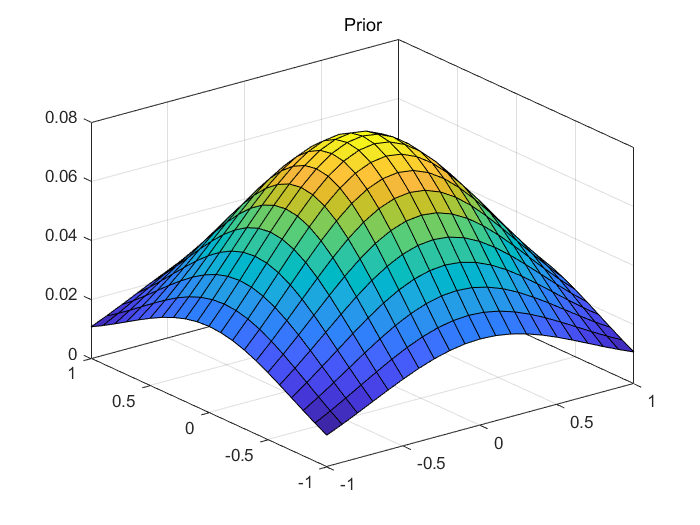

%% COMPUTATION
for i = 1:length(w1)                                        % goes through the indices of the domain in first dimension
    for j = 1:length(w2)                                    % goes through the indices of the domain in second dimension
        w = [w1(i) w2(j)] ;                                 % value of the domain point
        prior(i,j) = (1/(2*pi))*exp(-norm(w)^2)/2 ;         % value of the prior for every data-point, a gaussian here
    end
end

%% PLOT
figure                          % creates a new plot window
surf(w1,w2,prior)               % plots the prior (in 3D)
grid on                         % shows a grid on the plot
box on                          % puts a box around the plot
title('Prior')                  % gives a title to the plot

## Using just the first 2 data-points

## Posteriors

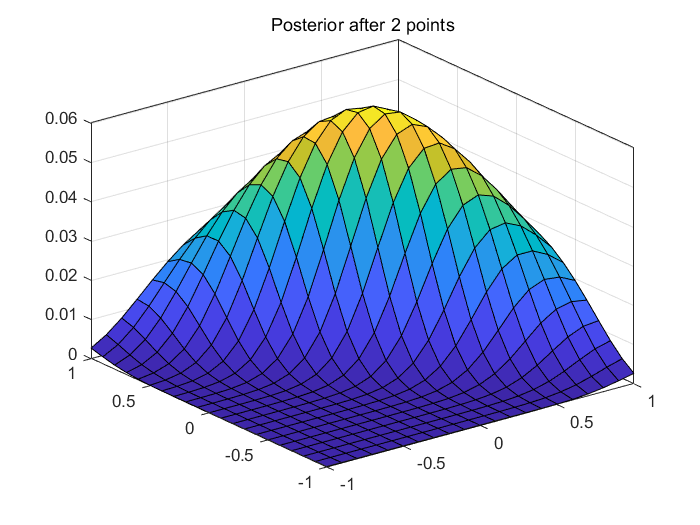

%% COMPUTATION
n = size(X2,1) ;                    % number of data-points
posterior = prior ;                 % before any additional information, the posterior is equal to the prior

for k = 1:n                                                 % goes through all data-points
    x = X2(k,:) ;                                           % value of the data-point
    for i = 1:length(w1)                                    % goes through the indices of the domain in first dimension
        for j = 1:length(w2)                                % goes through the indices of the domain in the second dimension
            w = [w1(i) w2(j)] ;                             % value of the domqin point
            y = 1/(1+exp(-w*x')) ;                          % transfer function
            likelihood = y^T2(k)*(1-y)^(1-T2(k)) ;          % likelihood (product of factors)
            posterior(i,j) = likelihood*posterior(i,j) ;    % posterior as a consequence of Bayes' theorem
        end
    end
end

%% PLOT
figure                              % creates a new plot window
surf(w1,w2,posterior)               % plots the posterior (in 3D)
grid on                             % shows a grod on the plot
box on                              % puts a box around the plot
title('Posterior after 2 points')   % gives a title to the plot

## Using all 4 data-points

Same algorithm, but with more data-points.

## Posteriors

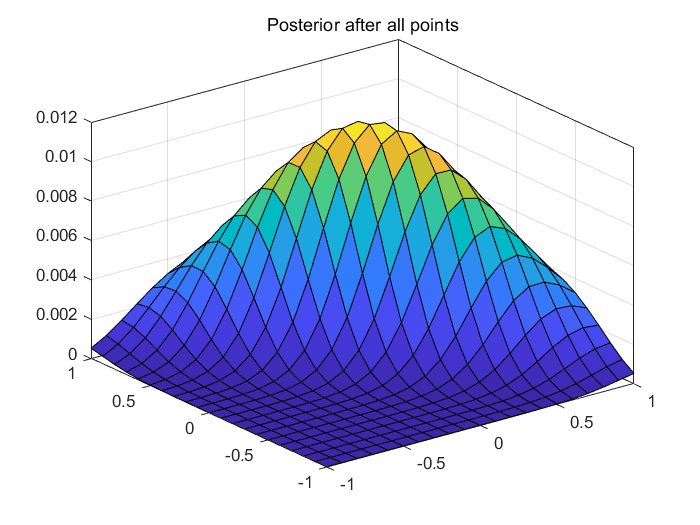

%% COMPUTATION
n = size(X4,1) ;
posterior = prior ;
for k = 1:n
    x = X4(k,:) ;
    for i = 1:length(w1)
        for j = 1:length(w2)
            w = [w1(i) w2(j)] ;
            y = 1/(1+exp(-w*x')) ;
            likelihood = y^T4(k)*(1-y)^(1-T4(k)) ;
            posterior(i,j)=likelihood*posterior(i,j) ;
        end
    end
end

%% PLOTS
figure
surf(w1,w2,posterior)
grid on
box on
title('Posterior after all points')